1.b.iii

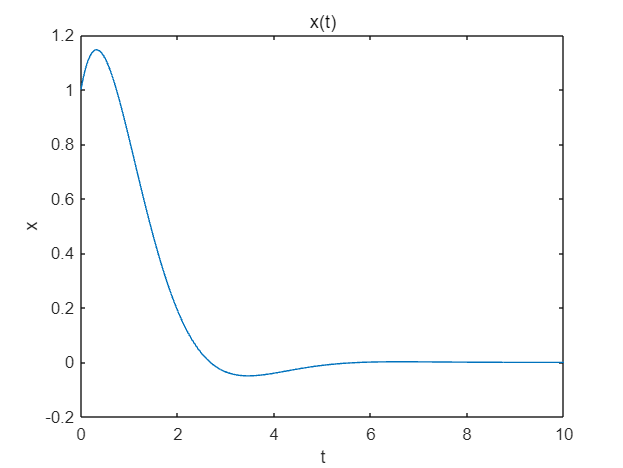

ts = 0:0.01:10;
c1 = 1; c2 = 2;

xt = @(ts) c1 .* exp(-ts) .* cos(ts) + c2 .* exp(-ts) .* sin(ts);

xs = xt(ts);

figure;
plot(ts, xs);
title("x(t)")
xlabel("t")
ylabel("x")

4. b

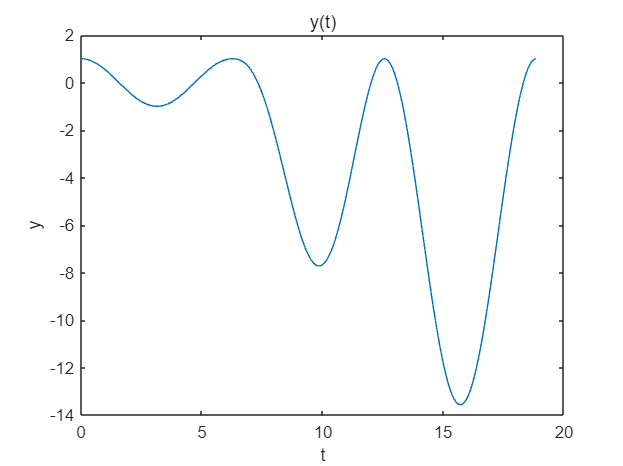

H = @(ts) (ts >= 0) .* ts + 0;

funcb = @(ts) cos(ts)-(-1 + cos(ts)).*H(-4*pi + ts) + (-1+ ... 
    cos(ts)) .* H(-2*pi + ts);

ts = 0:0.01:6*pi;
ys = funcb(ts);

figure;
plot(ts, ys);
title("y(t)")
xlabel("t")
ylabel("y")

4.c

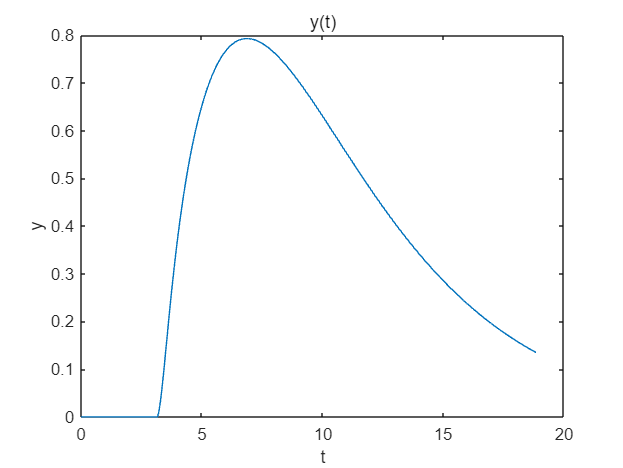

H = @(ts) (ts >= 0) .* ts + 0;

funcc = @(ts) -(((exp((-2-sqrt(3)).*(-pi+ts))-exp((-2+sqrt(3)) ...
    .*(-pi+ts))).*H(-pi+ts))./sqrt(3));

ts = 0:0.01:6*pi;
ys = funcc(ts);

figure;
plot(ts, ys);
title("y(t)")
xlabel("t")
ylabel("y")